Bote en el lago (Kalman Filter):

Se crea el vector de tiempos

dt=0.1; %Periodo de muestreo del sensor (segundos)
n=0:dt:599.9; %tiempo de navegación (10 min)

generación de los vectores de ruido:

Suposición: La intesidad del viento y las corrientes turbulencias son cero durante el primer minuto y luego cada minuto cambian de forma aleatoria

n_turbul=zeros([1 length(n)/10]);
for i=2:10
    n_turbul=[n_turbul randn zeros([1 length(n)/10-1])];
end
n_sensor=randn([1 length(n)]);

Inicialización de valores y matrices

%Condiciones iniciales
pos_0=0; %Posición inicial del bote (m)
vel_0=0; %Velocidad inicial del bote (m/s)
prop=3000; %Velocidad de las propelas (rpm)
%Filtro de Kalman
%Covarianza del sistema
Q=[1 0;
   0 1];
%Covarianza del sensor
R=1;
%Matriz de transición
F=[1 dt;
   0 1];
%Modelo de control
B=[0;
   0.01];
%Modelo de observación
H=[1 0];
%Vector de estados inicial
x_nn=[pos_0;
      vel_0];
%Matriz de covarianza a-posteriori
P=[1 0;
   0 1];

Loop del filtro de Kalman

%vectores de resultados
xre=zeros([2 length(n)]);
xes=xre;
xme=xre;
%impulso de las propelas
u=[prop zeros([1 length(n)-1])];
%Filtro de Kalman
x_re=x_nn;
for t=1:length(n)
    %Calculando el desplazamiento real del bote
    %(no se conoce y se pretende estimar)
    x_re=F*x_re+B*u(t)+[0;n_turbul(t)];
    
    %Calculando señal del sensor
    z=H*x_re+n_sensor(t);
    
    %PREDICCION
    x_nn=F*x_nn+B*u(t);
    P=F*P*F'+Q;
    
    %CORRECCIÓN
    y_m=z-H*x_nn;
    S=H*P*H'+R;
    K=P*H'*inv(S);
    x_nn=x_nn+K*y_m;
    P=(eye(2)-K*H)*P;
    
    %guardando valores para graficar
    xme(:,t)=z;
    xre(:,t)=x_re;
    xes(:,t)=x_nn;
end

Graficas del desplazamiento real y desplazamiento estimado

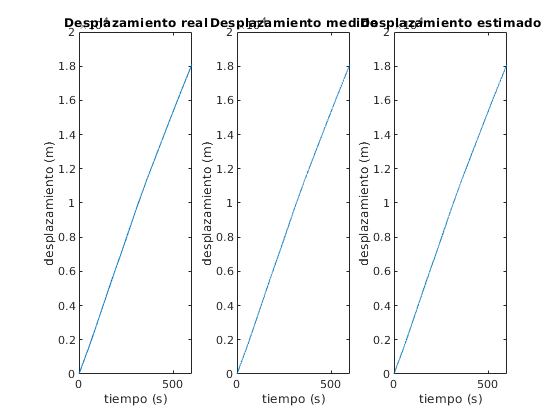

figure()
subplot(1,3,1)
plot(n,xre(1,:))
xlabel('tiempo (s)')
ylabel('desplazamiento (m)')
title('Desplazamiento real')
subplot(1,3,2)
plot(n,xme(1,:))
xlabel('tiempo (s)')
ylabel('desplazamiento (m)')
title('Desplazamiento medido')
subplot(1,3,3)
plot(n,xes(1,:))
xlabel('tiempo (s)')
ylabel('desplazamiento (m)')
title('Desplazamiento estimado')

Graficas de velocidad real y velocidad estimada

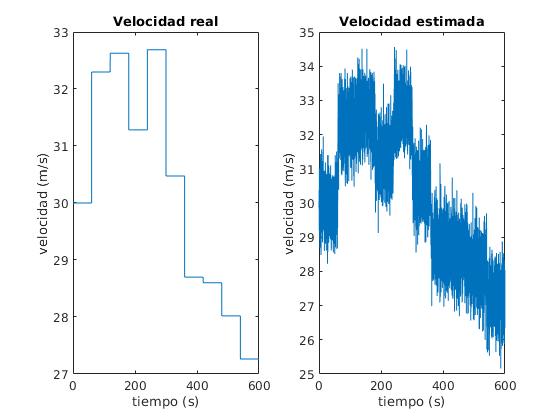

figure()
subplot(1,2,1)
plot(n,xre(2,:))
xlabel('tiempo (s)')
ylabel('velocidad (m/s)')
title('Velocidad real')
subplot(1,2,2)
plot(n,xes(2,:))
xlabel('tiempo (s)')
ylabel('velocidad (m/s)')
title('Velocidad estimada')